# **Mars Mission**

This live script intends to clean up the previously written .m file. 

The known variables in the project are as follows:

% Project Constants
% Daughter-Craft
h_dc = 400*1000; % m
R_mars = 3396.19*1000; % m
r_LMO = R_mars + h_dc; % m

mio_mars = 42828.3*10^9; % m^3/s^2
theta_dot_LMO = sqrt(mio_mars / (r_LMO^3));  % rad/s

sigma_BN_0 = [0.3;-0.4;0.5];
w_BN_0 = [1.00;1.75;-2.20] * pi/180; % rad/s

I_dc = diag([10;5;7.5]); % kg.m^2

RA_dc = 20 * pi/180; % DC right ascention
i_dc = 30 * pi/180;  % DC Inclination
theta_dc_0 = 60 * pi/180; % DC initial angle

% Mother-Craft
T_mc = (1*24*60 + 37)*60; % sec
r_GMO = 20424.2*1000; % m
theta_dot_GMO = sqrt(mio_mars / (r_GMO^3));  % rad/s

RA_mc = 0;
i_mc = 0;
theta_mc_0 = 250 * pi/180; % MC initial angle

## Task 1 - Orbit Simulation

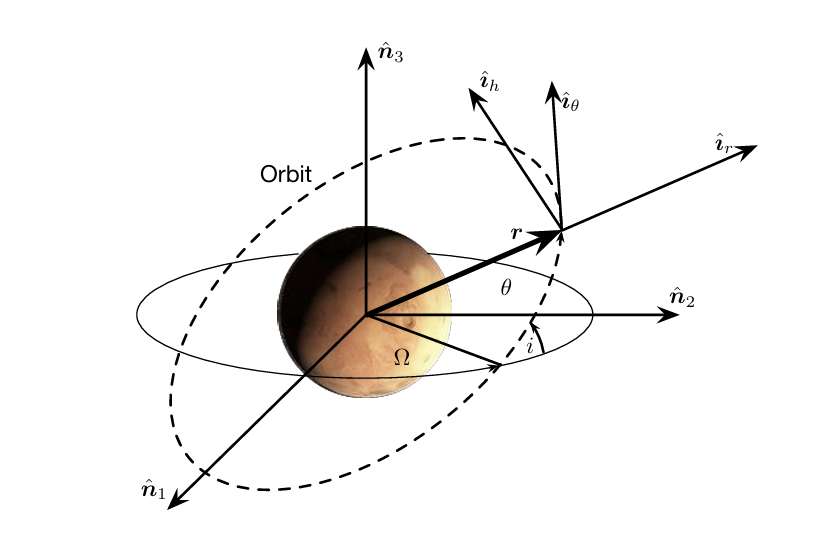

As seen in the picture above, we have the inertial frame as $\mathcal{N} : \{\hat{\mathbf{n}}_1,\hat{\mathbf{n}}_2, \hat{\mathbf{n}}_3\}$ and the Hill frame as $\mathcal{H} : \{\hat{\mathbf{i}}_r,\hat{\mathbf{i}}_\theta, \hat{\mathbf{i}}_h\}$. 

The task asks to:

- Derive the inertial spacecraft velocity vector $\mathbf{\dot{r}$. Note that for a circular orbit, $\dot{\theta}$ is constant.

- Write a function whose inputs are the radius $r$ and the (3-1-3) Euler angles ($\Omega,i,\theta$) and the outputs are the inertial position vector ${}^Nr$and ${}^N{\dot{r} }$of the associated circular orbit.

- Confirm the operation of this program by entering the inertial position and velocity vector results for ($r_{LMO}, \Omega_{LMO}, i_{LMO}, \theta_{LMO}(450s)$) and ($r_{GMO}, \Omega_{
GMO}, i_{GMO}, \theta_{GMO}(1150s)$).

### Answer

- Writing in general orbit frame, $\mathcal{O} : \{\hat{\mathbf{i}}_r,\hat{\mathbf{i}}_\theta, \hat{\mathbf{i}}_h\}$, we would have the position vector as:


$$\mathbf{r} = r\hat{\mathbf{i}_r}$$


            and, thus the velocity vector in general orbit frame would be:

   
$$\dot{\mathbf{r}} = r\dot{\theta}\hat{\mathbf{i}}_\theta$$


            since the motion is planar and the orbit is circular.

            Now for taking this into the inertial frame, we need to find the $[\mathcal{N}\mathcal{O}]$. We will find this using the (3-1-3) Euler angles as such:


$$[\mathcal{N}\mathcal{O}]_t = [R_3(\theta_t)R_1(i)R_3(\Omega)]^T$$


            So, in order to find the inertial spacecraft velocity vector $\mathbf{\dot{r}$ at a given time $t$, we'll have:


$${}^N{\dot{r} }=$$

$$[\mathcal{N}\mathcal{O}]_t$$

$${}^O{\dot{r} }$$


            2. The function is written as below:

function [r,r_dot] = orbit_state(r,Omega,i,theta,theta_dot)

% Since the motion is planar and circular, at any time we have
% r_dot = 0 i_r + r*theta_dot i_theta + 0 i_h

r_O = [r;0;0];
r_dot_O = [0;r*theta_dot;0];

ON = M3(theta)*M1(i)*M3(Omega);
NO = transpose(ON);

% Taking the B frame vectors to the N frame
r = NO*r_O;
r_dot = NO*r_dot_O;

end

            3. Operation goes as follows: